# 1. DSP OF ANALOG SIGNALS

## 1.1 Ideal C/D conversion

Let us consider the system in Fig. 1, where the continuous-time signal xc(t) is generated and converted

to digital by using an ideal D/C converter.

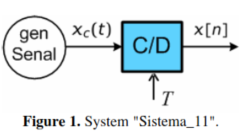

System parameters for simulating system "sistema11"  are included in the file parametros11.m,  and listed in the top of next page.

Run a simulation for the system "ejecutando" using the script practica11. The representation of the signals xc(t) and x[n], both in time and frequency domains, should appear in a set of figures.

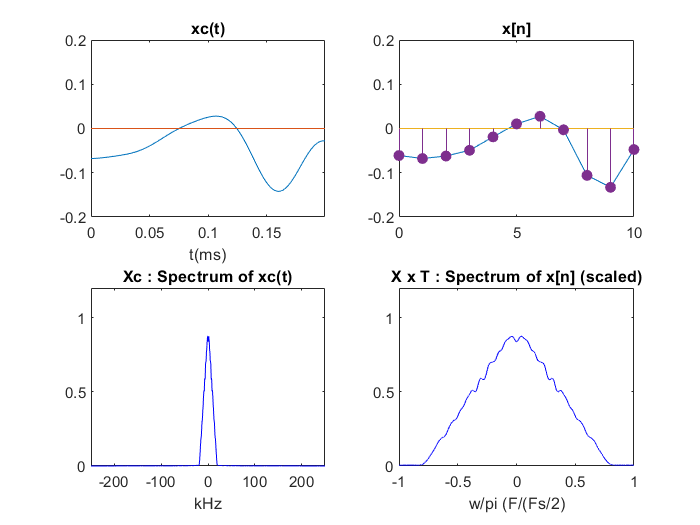

%practica11
inicio
parametros11
sistema11
graficas11

#### 1. With  the considered  set of parameters:  is Nyquist  criterion  met?  What's the minimum sampling frequency that can be used to sample xc(t) without aliasing?.

$\omega_n =40000\pi \;\;$(bandwidth)

$\omega_s =96000\pi$  (sampling)


$$\begin{array}{l}
\omega_s >2\omega_n \to \textrm{Nyquist}\;\textrm{Th}\;\textrm{is}\;\textrm{met}\\
\omega_{\textrm{smin}} =2\omega_n =80000\pi 
\end{array}$$


####  2.   With  the  set  of  parameters   previously   considered,    what   discrete   frequency  $\omega_n$ corresponds  to   the   maximum   frequency   of   the  signal    xc(t)    from  a  theoretical  perspective? Confirm your guess by observing this value in the plots.

Discrete freq.: $\Omega_n =2\pi \cdot f_p =40000\pi ;\;\omega_{n\;\;\;} =\Omega_n \cdot T=\Omega_n \cdot \frac{1}{f_s }=\frac{40000\pi }{48000}=\frac{5\pi }{6}\to \frac{5}{6}\approx 0\ldotp 83$

Measured value: 0.8

#### Question 3. Re-run the simulation for a signal xc(t) with bandwidth  Fp=5kHz. Answer again Question #2 in this new situation.

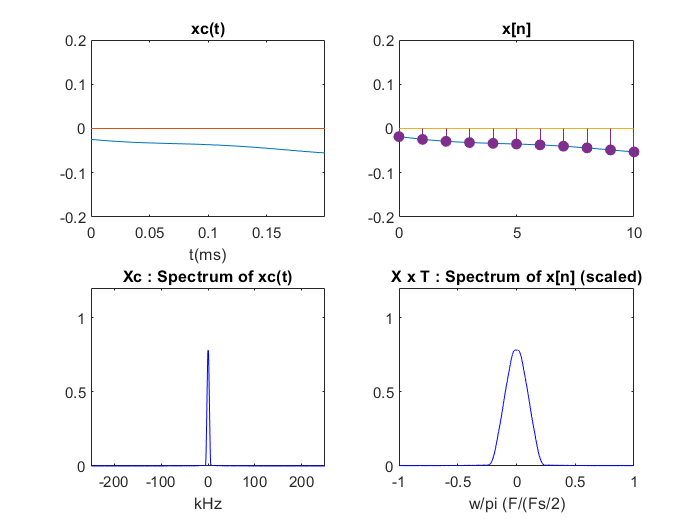

inicio
parametros11
sistema11
graficas11

Discrete freq.: $\Omega_n =2\pi \cdot f_p =10000\pi ;\;\omega_{n\;\;\;} =\Omega_n \cdot T=\Omega_n \cdot \frac{1}{f_s }=\frac{10000\pi }{48000}=\frac{5\pi }{24}\to \frac{5}{24}\approx 0\ldotp 2083$

Measured value: 0.23

#### Question 4. Re-run the simulation for a signal xc(t) with bandwidth Fp=30 kHz. How would you explain the results now obtained?

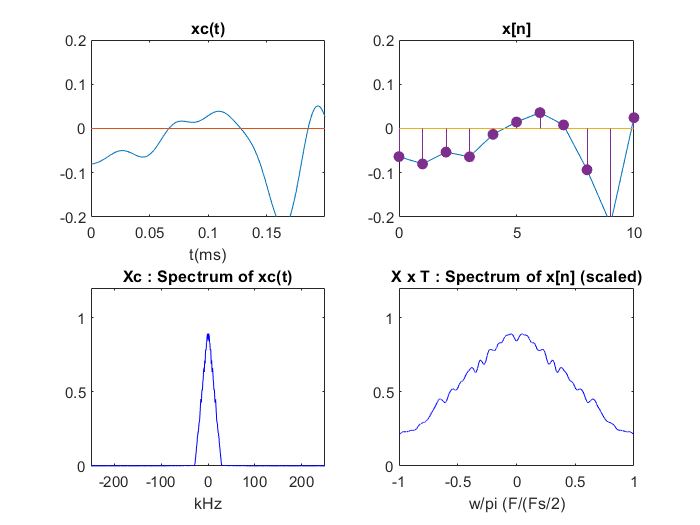

inicio
parametros11
sistema11
graficas11

Nyquist Th is not met (${f_s <2f}_n \to 48000<60000$).

## 1.2 Ideal C/D conversion and real D/A conversion

Let  us  consider  the  system  in  Fig.  2,  on  which  the  continuous-time  signal  xc(t)  is  generated  and

converted  into  the  discrete-time  signal   x[n],   first   by   using   an   ideal   C/D   converter,  and  then coverted back into the continuous-time domain by using a real D/A converter. See that two new signals are defined in the figure:  ximp(t), i.e., the output of the sequence to impulse converter, and  xret(t), i.e., the output of the reconstruction filter of zero-order hold.

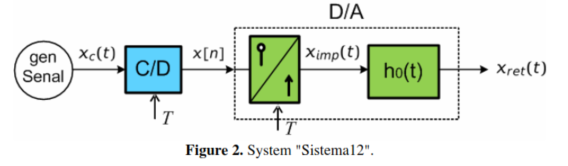

Simulation parameters for the system "sistema12"  are included in the file parametros12.m,  and also listed below. See that a flat-spectrum signal is now being used.

Run  the simulation  for the system  "sistema12" using script  practica12.  Three figures should pop-up:

In  the  first  one,  a  portion   of  the  4  continuous-time   signals   in  Figure   2  is  depicted.   In the second  and third ones,  the spectrums  of these  signals  are represented  in linear  scale and log-scale, respectively.  In the plots of the spectrums of ximp(t)  and xret(t), the frequency response of the zero- order hold filter is superimposed in red color.

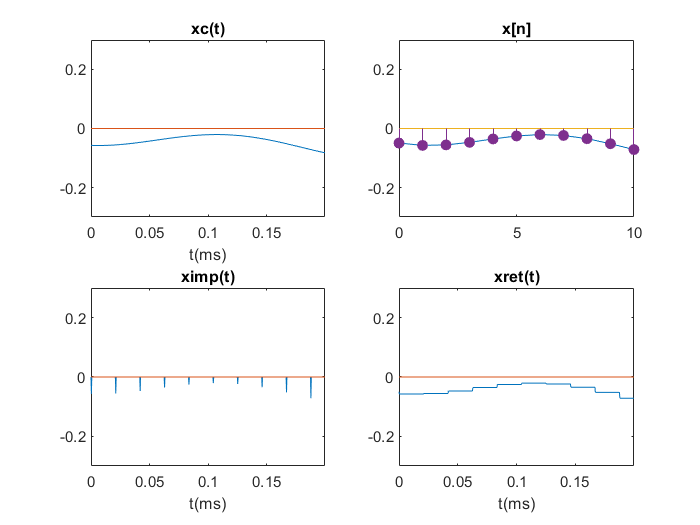

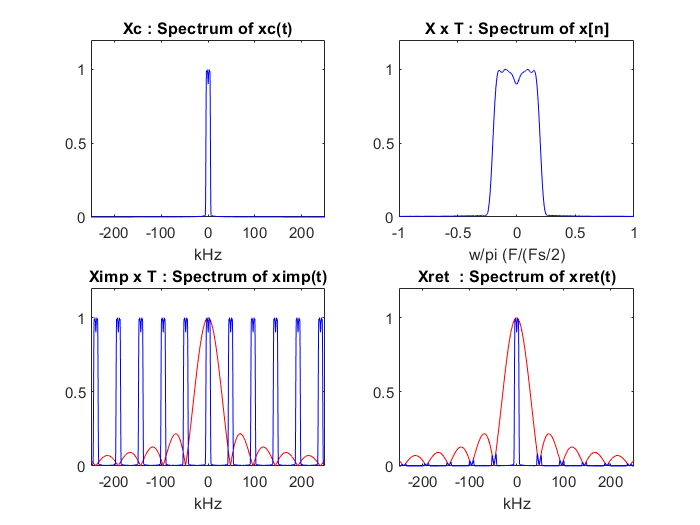

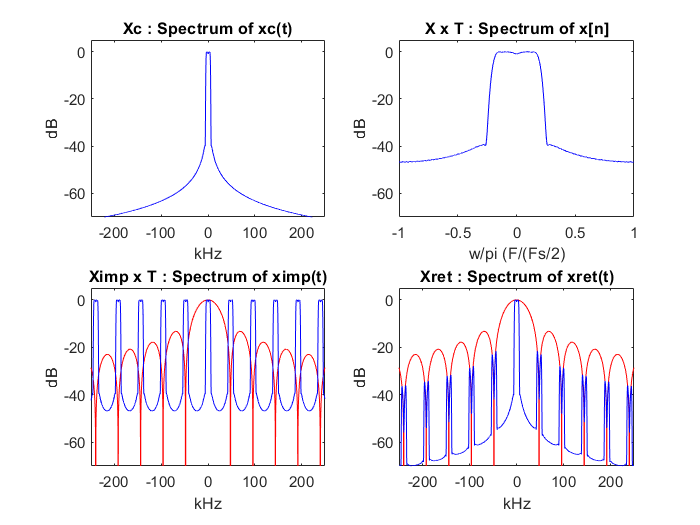

inicio
parametros12
sistema12
graficas12

#### Question  5.  Seeing the spectrum of xret(t):  What's  the  frequency  on which  the  first  image  replica begins?  What's  the center  frequency  for the image  replica?  Are these  values  coincident  with those predicted by theory?

Begin (theory): $f_s -f_n =\left(48000-20000\right)=28\;\textrm{kHz}$

Begin (measured): 27.75 kHz

Center freq. (theory): $f_s =48\textrm{kHz}$

Center freq. (measured): 47.625 kHz

#### Question  6. According  to theory: What's the attenuation  caused by the zero-order  hold filter at the beginning  of the image  replica?  Double-check  that this result is coincident  with that deduced  from the plot of the spectrum of  xret(t).

Fs=48000;
Fp=20000;
T=1/Fs;
omega=2*pi*(Fs-Fp);
H0=20*log10(abs(sin(omega*T/2)/(omega*T/2)))

H0 = -5.5625


$$\left|H_o \left(\Omega \right)\right|=\left|\frac{\mathrm{sin}\left(\frac{\Omega T}{2}\right)}{\frac{\Omega T}{2}}\right|=\left|\frac{\mathrm{sin}\left(\frac{\omega_n }{2}\right)}{\frac{\omega_n }{2}}\right|=\left|\frac{\mathrm{sin}\left(20000\pi \right)}{20000\pi }\right|=5\ldotp 5625$$


0.217233

inicio
parametros12
sistema12
graficas12

Begin (theory): $f_s -f_n =\left(48000-5000\right)=43\;\textrm{kHz}$

Begin (measured): 41.625 kHz

Center freq. (theory): $f_s =48\textrm{kHz}$

Center freq. (measured): 48 kHz

## 1.3 Ideal C/D conversion & D/A conversion with oversampling

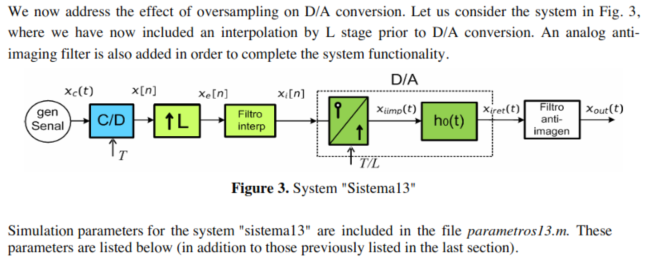

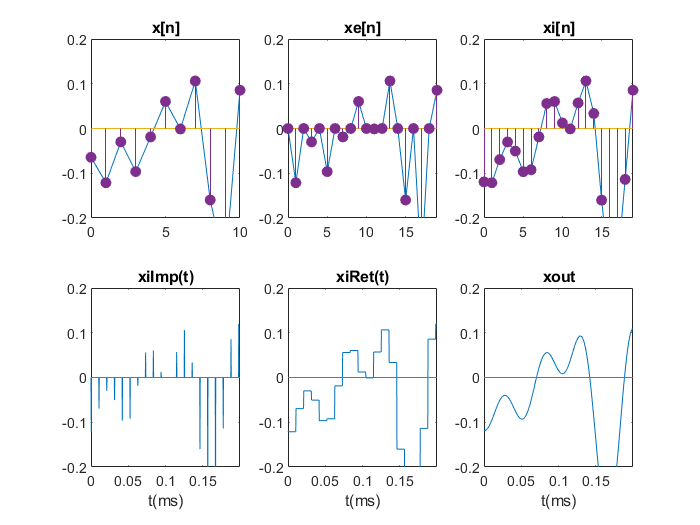

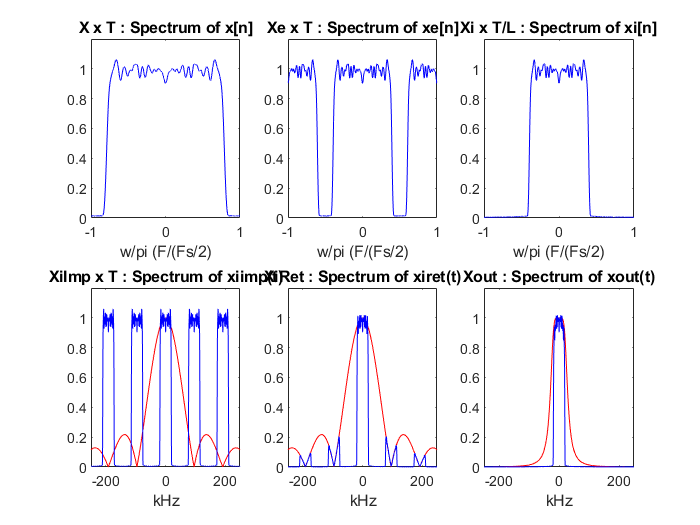

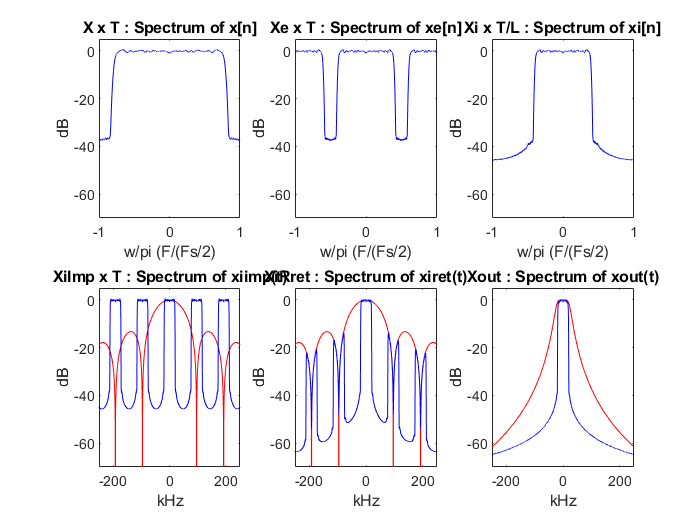

inicio
parametros13
sistema13
graficas13

Run the simulation for the system "sistema13" using script practica13; three figures should show up.

Three figures should pop-up: In the first one, a portion of the 6 continuous-time signals in Figure 3 is depicted. In the second and third ones, the spectrums of these signals are represented in linear scale and log-scale, respectively. In the plots of the spectrums of ximp(t) and xret(t), the frequency response of the zero-order hold filter is superimposed in red color.

In the plots of the spectrum of xout(t), the frequency response of the anti-imaging filter is also superimposed in red color.

#### Question 8 Describe the main differences between the signals xret(t) in system "sistema12" and xiret(t), both in time and frequency domains.

It increases the amplitude of the images, but it also offsets the signal (by a factor of 2). 

#### Question  9.  If we were to choose a larger value of L, would it be beneficial or detrimental for the reconstruction of the signal? Verify your guess by running the simulation with L=4.

It would be benefitial for the reconstruction, given that it would increase the distance between samples and thus facilitate the filtering process. 

For L=4, instead of a center freq. of $\approx 50\;\textrm{kHz}$, it would be of $\approx 200\;\textrm{kHz}$, as proven in the graphical views. 

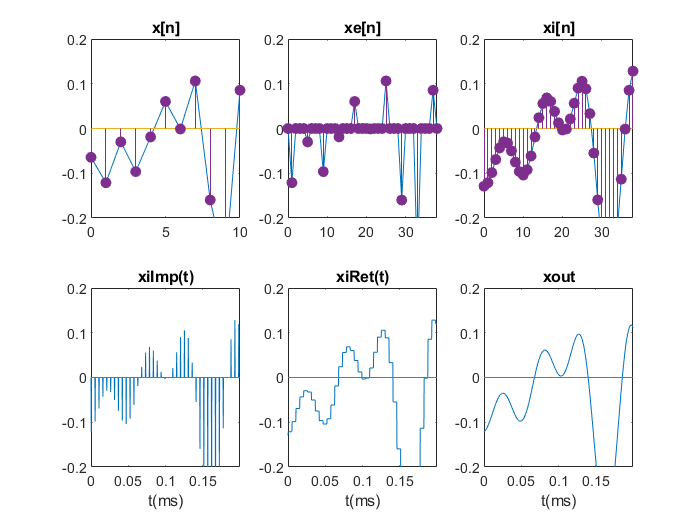

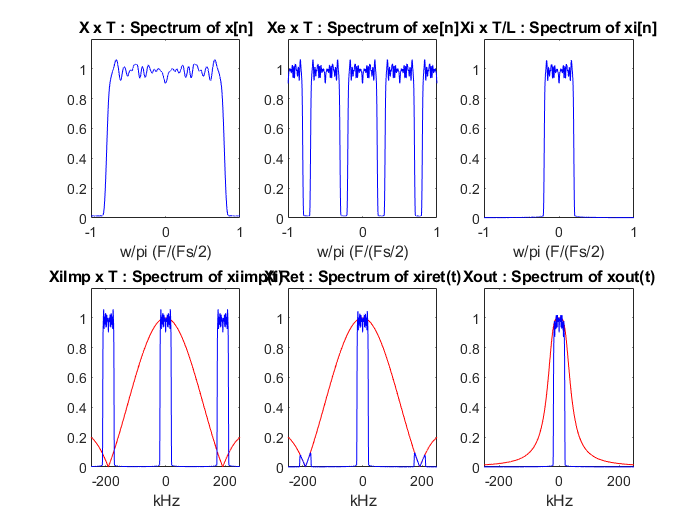

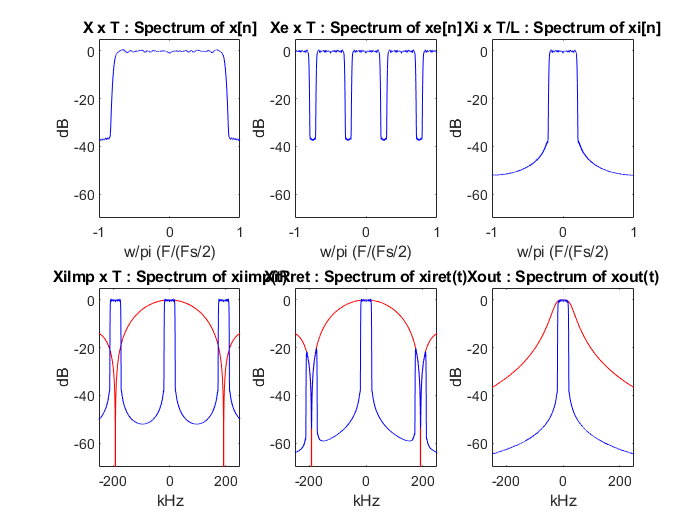

inicio
parametros13
sistema13
graficas13

#### Question  10.  Type  help expande to  see  the  header  of  the  function  in  charge  of  expanding the signal. Following  these guidelines,  write  your  own  Matlab  function  "expande2"  that  performs the expansion  of a signal  by a factor  L. Check  that  it works  with  a toy example,  and  then  add  it up  to the  library.  Change  the  instances  to  "expande"  in  "sistema13"  to  use  your  newly  designed function. Run the simulation of the system ""sistema13" to see that everything works fine.

help expande

  -----------------------------------------------------------
  Expansion
  -----------------------------------------------------------
  xe = expande(x, L)
  -----------------------------------------------------------
     x:   input signal vector
     xe:  output signal vector (expanded)
     L:   Expansion by L
  -----------------------------------------------------------



inicio
parametros13
sistema13_2
graficas13